run highFidelityTiltingQuadrotorData.m

syms t real positive

benchmarck_trj = 2;
A = [
    2 1
    3 1.5
    4 2
    5 2.5
    6 3
    7 3.5
    8 4
    ];

% desired position not smoothed [m]

p_unsmoothed(t) = [
    A(benchmarck_trj,1)*sin(t)
    A(benchmarck_trj,2)*sin(2*t)
    0
    ]

$$p\_unsmoothed(t) = \left(\begin{array}{c} 3\,\sin\left(t\right)\\ \frac{3\,\sin\left(2\,t\right)}{2}\\ 0 \end{array}\right)$$

% desired veloocity not smoothed [m/s]
v_unsmoothed(t) = diff(p_unsmoothed,t)

$$v\_unsmoothed(t) = \left(\begin{array}{c} 3\,\cos\left(t\right)\\ 3\,\cos\left(2\,t\right)\\ 0 \end{array}\right)$$

% desired acceleration not smoothed [m/s2]
a_unsmoothed(t) = diff(v_unsmoothed,t)

$$a\_unsmoothed(t) = \left(\begin{array}{c} -3\,\sin\left(t\right)\\ -6\,\sin\left(2\,t\right)\\ 0 \end{array}\right)$$


p_unsmoothed_ic = p_unsmoothed(0);
v_unsmoothed_ic = v_unsmoothed(0);
a_unsmoothed_ic = a_unsmoothed(0);

smoother_frequencies = [-1 -2 -3];
A = [
    1 1 1
    smoother_frequencies
    smoother_frequencies.^2
    ];
smoother = sym('smoother',[3 1], 'real');
for k=1:3
    B = [
        p_unsmoothed_ic(k)
        v_unsmoothed_ic(k)
        a_unsmoothed_ic(k)
        ];
    smoother_coef = linsolve(A,B);
    smoother(k) =  exp(smoother_frequencies*t) * smoother_coef;
end

% smoothed desired position [m]
p(t) = p_unsmoothed(t) - smoother;
% smoothed desired velocity [m/s]
v(t) = diff(p,t);
% smoothed desired acceleration [m/s2]
a(t) = diff(v,t);
% smoothed jerk [m/s3]
j(t) = diff(a,t);

% desired quaterion, TO-DO ADD QUATERNIO SMOOTHER!
q(t) = sym([
    1
    0
    0
    0
    ])

$$q(t) = \left(\begin{array}{c} 1\\ 0\\ 0\\ 0 \end{array}\right)$$

%q(t) = sym(eul2quat([0,pi/6,0])') 

% quaternion derivative
q_dot = diff(q,t);

q_mat = q(t);
eta = q_mat(1);
epsilon = q_mat(2:4);
epsilon_x = [0, -epsilon(3), epsilon(2); epsilon(3), 0, -epsilon(1); -epsilon(2), epsilon(1), 0];
Mq = [eta, -epsilon'; epsilon, eta*eye(3)+epsilon_x];
Rq = eye(3) + 2*eta*epsilon_x + 2*epsilon_x^2;  % rotation matrix, body to world

% angular rate
omega(t)    = simplify(Mq\q_dot);
omega_mat   = omega(t);
omega(t)    = omega_mat(2:4)

$$omega(t) = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$


% angular acceleration
omega_dot(t)    = diff(omega,t);
omega_ddot(t)   = diff(omega,t);

Ts_st = 0.01;   % shooting interval time, must match the one of the NMPC
Tmax = 40;      % trajectory duration

tt = Ts_st*(0:floor(Tmax/Ts_st));

des_p = double(cell2sym(p(tt)));
des_q = double(cell2sym(q(tt)));
des_v = double(cell2sym(v(tt)));
des_omega = double(cell2sym(omega(tt)));

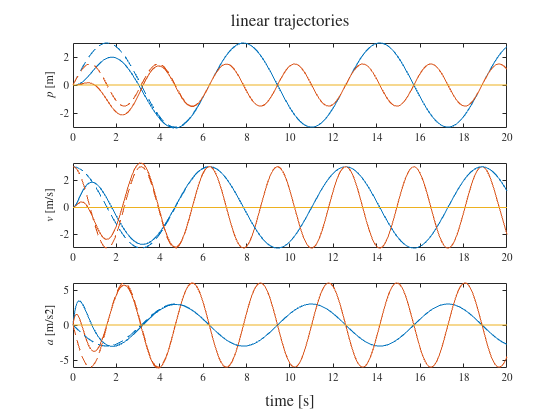

Tplot = 20; % [s]

figure(1)
tl = tiledlayout(3,1);
xlabel(tl,"time [s]", 'interpreter','latex')
title(tl, "linear trajectories", 'interpreter','latex')

nexttile
plot_t = p(t);
fplot(plot_t(1),[0 Tplot])
set(gca,'NextPlot','add')
fplot(plot_t(2),[0 Tplot])
fplot(plot_t(3),[0 Tplot])
set(gca,'ColorOrderIndex',1)
plot_t = p_unsmoothed(t);
fplot(plot_t(1),[0 Tplot],'--')
fplot(plot_t(2),[0 Tplot],'--')
fplot(plot_t(3),[0 Tplot],'--')
ylabel('$p$ [m]')

nexttile
plot_t = v(t);
fplot(plot_t(1),[0 Tplot])
set(gca,'NextPlot','add')
fplot(plot_t(2),[0 Tplot])
fplot(plot_t(3),[0 Tplot])
set(gca,'ColorOrderIndex',1)
plot_t = v_unsmoothed(t);
fplot(plot_t(1),[0 Tplot],'--')
fplot(plot_t(2),[0 Tplot],'--')
fplot(plot_t(3),[0 Tplot],'--')
ylabel('$v$ [m/s]')

nexttile
a_mat = a(t);
fplot(a_mat(1),[0 Tplot])
set(gca,'NextPlot','add')
fplot(a_mat(2),[0 Tplot])
fplot(a_mat(3),[0 Tplot])
set(gca,'ColorOrderIndex',1)
a_mat = a_unsmoothed(t);
fplot(a_mat(1),[0 Tplot],'--')
fplot(a_mat(2),[0 Tplot],'--')
fplot(a_mat(3),[0 Tplot],'--')
ylabel('$a$ [m/s\^2]')

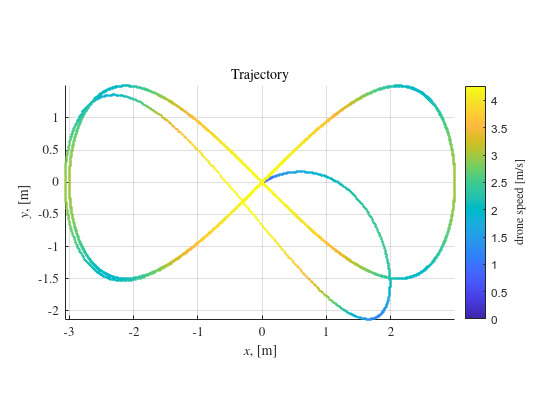

figure
scatter3(des_p(1,:), des_p(2,:), des_p(3,:), ...
    [],vecnorm(des_v,2,1),'.')
axis equal
view(0,90);
xlabel("$x$, [m]")
ylabel("$y$, [m]")
zlabel("$z$, [m]")
title("Trajectory")
c = colorbar;
c.Label.String = "drone speed [m/s]";
c.Label.Interpreter = 'latex';

## From trj to body thrust and torques


$$$\dot{\mathbf{v}} = \pmatrix{ 0 \cr 0 \cr -g} + \frac{1}{m_b}\mathbf{R}_b \mathbf{T}$$



$$\mathbf{\tau}_{tot} = \mathbf{I}_b \dot{\mathbf{\omega}} + \mathbf{\omega} \times \mathbf{I}_b \mathbf{\omega}$$


T(t) = tiltq.m_b * (Rq \ (a-[0;0;-9.81]))

$$T(t) = \left(\begin{array}{c} -\frac{393\,{\mathrm{e}}^{-3\,t}\,\left(5\,{\mathrm{e}}^{2\,t}-32\,{\mathrm{e}}^{t}+2\,{\mathrm{e}}^{3\,t}\,\sin\left(t\right)+27\right)}{100}\\ -\frac{393\,{\mathrm{e}}^{-3\,t}\,\left(5\,{\mathrm{e}}^{2\,t}-32\,{\mathrm{e}}^{t}+4\,\sin\left(2\,t\right)\,{\mathrm{e}}^{3\,t}+27\right)}{100}\\ \frac{128511}{5000} \end{array}\right)$$

tau_tot(t) = body.I * omega_dot + cross(omega, body.I*omega)

$$tau\_tot(t) = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

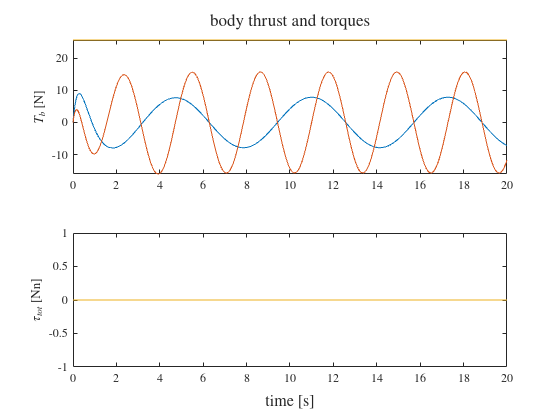

T_and_tau(t) = [
    T
    tau_tot
    ];

des_T_and_tau = double(cell2sym(T_and_tau(tt)));

figure
tl = tiledlayout(2,1);
title(tl, "body thrust and torques", 'Interpreter','latex')
xlabel(tl,"time [s]", 'interpreter','latex')

nexttile
fplot(T,[0 Tplot])
ylabel('$T_b$ [N]')

nexttile
fplot(tau_tot,[0 Tplot])
ylabel('$\tau_{tot}$ [Nn]')

### From body thrust and torques to tilting angles and spinning rate square

w_bar2 = sym('w_bar2', [4 1], {'real', 'positive'});
alpha = sym('alpha', [4 1], 'real');
syms bRi [3 3] matrix
Th = sym('Th', [3 4]);
tauh = sym('tauh', [3 4]);

for k=1:4
    bRi = [
        cos(tiltq.beta(k)) -sin(tiltq.beta(k)) 0
        sin(tiltq.beta(k)) cos(tiltq.beta(k)) 0
        0                   0                   1
        ]*[
        1 0             0
        0 cos(alpha(k)) -sin(alpha(k))
        0 sin(alpha(k)) cos(alpha(k))
        ];
    tb = bRi*[0;0;1].*prop.k_t.*prop.w_max.^2;
    Th(:,k) = tb;
    tauh(:,k) = cross(tiltq.p_mot(k,:).', tb) - ...
        prop.c_direction(k) * prop.m_t_ratio * tb;
end
alloc = [
    Th
    tauh
    ];
f([alpha; w_bar2]) = alloc*w_bar2;
target = sym('target',[6 1]);
constraint([alpha; w_bar2; target]) = target-f;
constraintGrad([alpha; w_bar2]) = jacobian(constraint, [alpha; w_bar2]).';
cost([alpha; w_bar2]) = (alpha).'*(alpha) + 10*(w_bar2).'*(w_bar2);
costgrad([alpha; w_bar2]) = gradient(cost,[alpha; w_bar2]);
costhessian([alpha; w_bar2]) = hessian(cost,[alpha; w_bar2]);
cost_handle = matlabFunction(cost, costgrad, costhessian, 'Vars',{[alpha;w_bar2],target}, 'File', 'trjCost');
constraint_handle = matlabFunction(constraint, constraintGrad, 'Vars',{[alpha;w_bar2],target}, 'File', 'trjConstraint');
%hessian_handle = matlabFunction(costhessian, 'Vars',{[alpha;w_bar2],target}, 'File', 'trjHessian');

x = zeros(8,length(tt));
x0 = x(:,1);

optoptions = optimoptions('fmincon', ...
    'Algorithm','interior-point',...
    'SpecifyObjectiveGradient',true,...
    'SpecifyConstraintGradient',true,...
    'Display','notify');
    %'HessianFcn','objective',...
    %

lb = [
    -pi*ones(4,1)
    0.01*ones(4,1)
    ];
ub = [
    pi*ones(4,1)
    ones(4,1)*inf
    ];

for k=1:length(tt)
%     optoptions = optimoptions(optoptions, ...
%         'HessianFcn',@(x) trjHessian(x,des_T_and_tau(:,k)));
    x(:,k) = fmincon( ...
        @(x) trjCost(x,des_T_and_tau(:,k)), ... % function to minimize
        x0, ... % initial conditions
        [], [], ... % A,b for linear inequalities
        [], [], ... % Aeq, beq for linear equalities
        lb, ub, ... 
        @(x) trjConstraintBuilder(x,des_T_and_tau(:,k)), ...
        optoptions);
    x0 = x(:,k);
end
des_alpha = x(1:4,:);
des_w_bar2 = x(5:8,:);

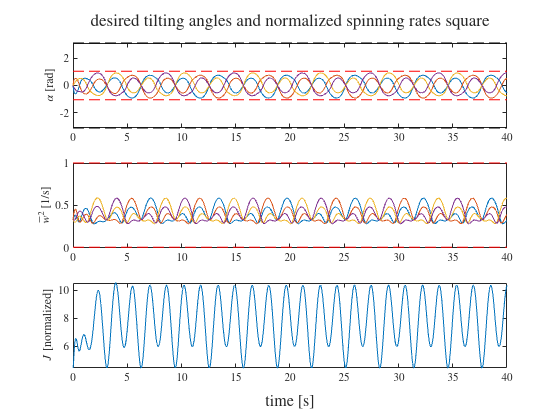

figure
tl = tiledlayout(3,1);
xlabel(tl,"time [s]", 'interpreter','latex')
title(tl,'desired tilting angles and normalized spinning rates square', 'Interpreter','latex')

nexttile
plot(tt,des_alpha)
hold on
plot([tt(1) tt(end)], lb(1)*[1 1], 'k--')
plot([tt(1) tt(end)], ub(1)*[1 1], 'k--')
plot([tt(1) tt(end)], -pi/3*[1 1], 'r--')
plot([tt(1) tt(end)], pi/3*[1 1], 'r--')
ylabel('$\alpha$ [rad]')

nexttile
plot(tt,des_w_bar2)
hold on
plot([tt(1) tt(end)], lb(5)*[1 1], 'k--')
plot([tt(1) tt(end)], ub(5)*[1 1], 'k--')
plot([tt(1) tt(end)], 0.01*[1 1], 'r--')
plot([tt(1) tt(end)], 1*[1 1], 'r--')
ylabel('$\bar{w}^2$ [1/s]')

nexttile
plot(tt,trjCost(x, des_T_and_tau));
ylabel('$J$ [normalized]')

### Numerical derivation of tilting rates and spinning acceleration

des_alpha_dot = [ diff(des_alpha,1,2) ./ Ts_st, zeros(4,1)];
des_w_bar2_dot = [ diff(des_w_bar2,1,2) ./ Ts_st, zeros(4,1)];

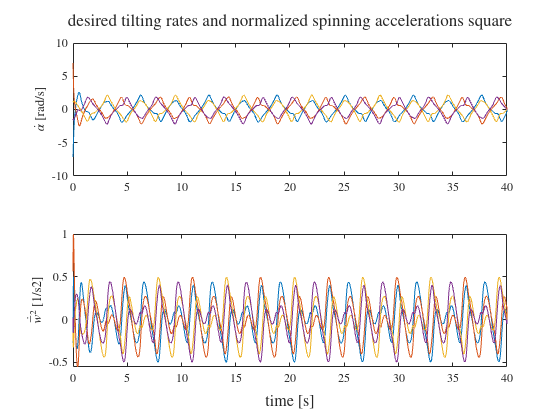

figure
tl = tiledlayout(2,1);
xlabel(tl,"time [s]", 'interpreter','latex')
title(tl,'desired tilting rates and normalized spinning accelerations square', 'Interpreter','latex')

nexttile
plot(tt,des_alpha_dot)
hold on
%plot([tt(1) tt(end)], lb(1)*[1 1], 'k--')
%plot([tt(1) tt(end)], ub(1)*[1 1], 'k--')
ylabel('$\dot{\alpha}$ [rad/s]')

nexttile
plot(tt,des_w_bar2_dot)
hold on
%plot([tt(1) tt(end)], lb(5)*[1 1], 'k--')
%plot([tt(1) tt(end)], ub(5)*[1 1], 'k--')
ylabel('$\dot{\bar{w}}^2$ [1/s2]')

Save reference trj

reference = [
    des_p
    repmat([0; 0; 0],size(tt))
    des_v
    des_omega
    des_alpha
    des_w_bar2
    des_w_bar2_dot
    des_alpha_dot
    ]';

des_a = double(cell2sym(a(tt)));
des_j = double(cell2sym(j(tt)));
des_omega = double(cell2sym(omega(tt)));
des_omega_dot = double(cell2sym(omega_dot(tt)));
des_omega_ddot = double(cell2sym(omega_ddot(tt)));

reference_FL = [
    des_p
    des_q
    des_v
    des_omega
    des_a
    des_omega_dot
    des_j
    des_omega_ddot
    ]';
if( ~exist('./custom_trajectories','dir')==7 )
    mkdir custom_trajectories
end
save('custom_trajectories/reference.mat','reference','des_q', 'tt', 'reference_FL', 'Ts_st');

prompt = "Do you to save the benchmark trj? Y/N [Y]: ";
txt = input(prompt,"s");
if isempty(txt)
    txt = 'Y';
end
if strcmp(txt,"Y")
    bench_path = sprintf('benchmark_trajectories/b%02i.mat',benchmarck_trj)
    save(bench_path,'reference','des_q', 'tt', 'reference_FL', 'Ts_st', "A", "benchmarck_trj");
end